% เคลียร์ข้อมูลก่อนรันโค้ดใหม่
clear all, close all, clc

% โหลดข้อมูลจาก m-file "split_data_train_test.mat"
load("split_data_train_test.mat")

% นำเข้าชุดข้อมูลที่จัดกลุ่ม
data = [X_train Y1_ElectricPower_train Y2_HeatRejection_train];

% การใช้วิธี k-means clustering
k = 474; % จำนวนกลุ่ม 25% ของชุดข้อมูล training set
[idx, centroids] = kmeans(data, k); % ทำการจัดกลุ่มและคำนวณ centroid

% เลือกค่าที่ใกล้เคียงกับ centroid ของแต่ละกลุ่ม 1 ค่า
X_sampling_training = zeros(k, size(X_train, 2));
Y1_sampling_training = zeros(k, 1);
Y2_sampling_training = zeros(k, 1);

for i = 1:k
    distances = sum((data - centroids(i, :)).^2, 2); % คำนวณระยะห่างระหว่างข้อมูลและ centroid
    [~, min_index] = min(distances); % เลือกข้อมูลที่ใกล้ที่สุดกับ centroid
    X_sampling_training(i, :) = X_train(min_index, :);
    Y1_sampling_training(i) = Y1_ElectricPower_train(min_index);
    Y2_sampling_training(i) = Y2_HeatRejection_train(min_index);
end

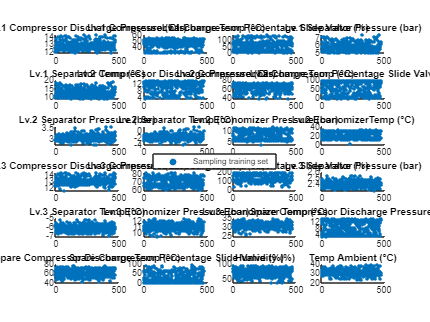


% Create subplots for each column
figure('Name','Sampling training set');
% figure;
for i = 1:size(clean_data, 2)-2
    subplot(6, 4, i);
    scatter(1:size(X_sampling_training,1), X_sampling_training(:,i), 10, 'filled');

    title(column_names{i});
%      legend('Raw', 'Cleaned');

end
% Create a common legend outside the subplot
legend('Sampling training set', 'Location','none');

figure;

for i = 1:size(X_train, 2)
    subplot(6, 4, i);
    plot(X_train(:, i),X_train(:, i), 'b.'); % พล็อตข้อมูลในคอลัมน์ที่ i
    hold on;
    plot(X_sampling_training(:, i),X_sampling_training(:, i), 'kx', 'MarkerSize', 10, 'LineWidth', 2); % พล็อต centroid
    hold off;
%     xlabel('Data Index');
%     ylabel(['Column ' num2str(i)]);
    title(column_names{i});
%     legend('Data', 'Centroid');
end

% figure;
% for i = 1:size(X_train, 2)
%     subplot(6, 4, i);
%     scatter(X_train(:, i), Y2_sampling_training, [], idx, 'filled');
% %     colormap(gca, jet(num_clusters));
% %     colorbar;
%     xlabel(column_names{i});
%     ylabel('Y1 - Electric Power');
% end
% 
% % figure;
% % for i = 1:size(X_train, 2)
% %     subplot(6, 4, i);
% %     scatter(X_train(:, i), Y2_sampling_training, [], idx, 'filled');
% %     colormap(gca, jet(num_clusters));
% %     colorbar;
% %     xlabel(column_names{i});
% %     ylabel('Y1 - Electric Power');
% % end
